# **LAB:  Bearing Fault Monitoring and RUL Estimation**

### **Name: Hong Se Hyun (21700791)**

### **Due in 1 week**

## **Instruction**

In this LAB, you are required to create a simple code for Fault Monitoring and RUL estimation

You can refer to RUL estimation tutorial codes and related papers

**Fault Monitoring**

- Detect Fault Status

- Display WARNING MESSAGE

**RUL Estimation **

- Estimate RUL similar to Tutorial codes

- The end of Life can be assumed when the repair is done

## 1-1. Dataset

Raw Dataset of Bearing Velocity measured that shows a Bearing Life cycle before the repair is done. Also the velocity measurement after the repair is provided.

Using the given dataset, develop simple program for

- Bearing velocity measured 24 times per day

- Each measurement is L=8192 with Fs=2560Hz  

- Measurement for consecutive days until repair is done

First visualize the vibration signals in the time domain. 

clear; close all; clc;

load("C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab_2\bearing_vel_fulldata.mat\");
% rows: vel measurements // cols: measurement time

%idx_repair = 1431;   % index repair
bearing     = bearingFulldata(:,1:idx_repair);       % Dataset Before Repair
bearingNew  = bearingFulldata(:,idx_repair+1:end);   % Dataset After Repair

% Data Length for each measurement
L = length(bearing(:,1))

L = 8192

% Sampling Frequency
fs = 2560;
ts = 1/fs;
t = 0 : ts : ts*(L-1);   % Total 3.2 second // we gathered data for 3.2 sec.


% Day(time) unit upto repair  // Dataset Before Repair
% dataN = (length(bearing(1, :)))/24;   % INTERVAL = DAY
% d     = (1 : 1 : dataN);
dataN = (length(bearing(1, :)));    % INTERVAL = HOUR
d     = (1 : 1 : dataN)/24;

Plotting bearing velocity raw data

- Initial state:  Day=0 

- Just before repair:  Day=59

- After repair:  Day=60

## 1-2. RAW Data   :   Bearing Velocity

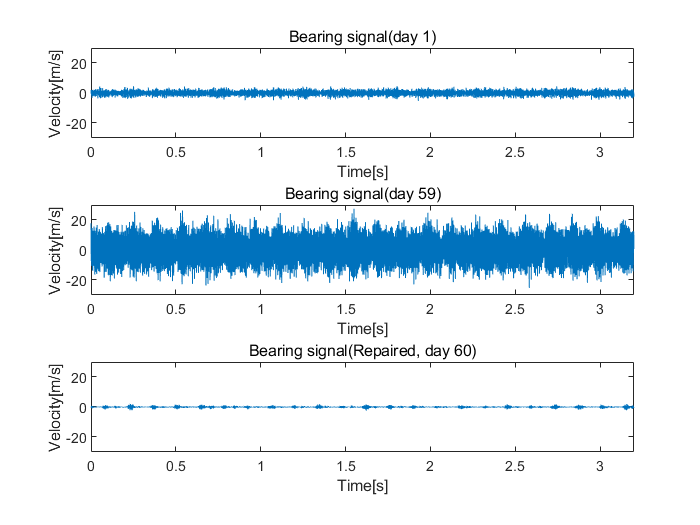

idx1 = 1;   idx2 = idx_repair;    idx3 = 1;

figure
subplot(3, 1, 1);       plot(t, bearing(:, idx1));      % 베어링 교체 전,   Day=0에서 측정한 Signal Plot
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(day 1)');
subplot(3, 1, 2);       plot(t, bearing(:, idx2));      % 베어링 교체 직전, Day=60에서 측정한 Signal Plot
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(day 59)');
subplot(3, 1, 3);       plot(t, bearingNew(:, idx3));   % 베어링 교체 후,   Day=60직후에서 측정한 Signal Plot
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(Repaired, day 60)');

## **2-1. Data Exporation and Pre-processing**

When plotting the RMS of the Raw Signal, it can be seen that many lines perpendicular to the x-axis are formed.

This seems to have been temporarily stopped for inspection or for various reasons.

Since the final purpose is to predict the life of the bearing, appropriate data pre-processing will be required for such a temporarily stopped section.

In other words, data pre-processing was required so that the graph of the RMS Value over time could be a continuous graph.

Here, for the stop section data, noise was removed by importing and overwriting the data immediately preceding data.

% Day(time) unit upto repair  // Dataset Before Repair
% dataN_Full                                       = (length(bearingFulldata(1, :)))/24;  % INTERVAL = DAY
% d_Full                                           = (1 : 1 : dataN_Full);                % INTERVAL = DAY
dataN_Full                                       = (length(bearingFulldata(1, :)));   % INTERVAL = HOUR
d_Full                                           = (1 : 1 : dataN_Full)/24;           % INTERVAL = HOUR

size_data = size(d_Full);
size_data = size_data(2);


RAW_bearingFulldata                              = bearingFulldata;
RAW_bearingFull_RMS                              = rms(RAW_bearingFulldata(:, :));

Preprocessed_bearingFulldata                     = bearingFulldata;
drop_column                                      = find(RAW_bearingFull_RMS<0.5);
Preprocessed_bearingFulldata(:,drop_column)      = Preprocessed_bearingFulldata(:,drop_column-1);
Preprocessed_bearingFull_RMS                     = rms(Preprocessed_bearingFulldata(:, :));

iteration = 3;
for i = 1 : iteration
    drop_column                                  = find(Preprocessed_bearingFull_RMS<0.5);
    Preprocessed_bearingFulldata(:,drop_column)  = Preprocessed_bearingFulldata(:,drop_column-1);
    Preprocessed_bearingFull_RMS                 = rms(Preprocessed_bearingFulldata(:, :));
end

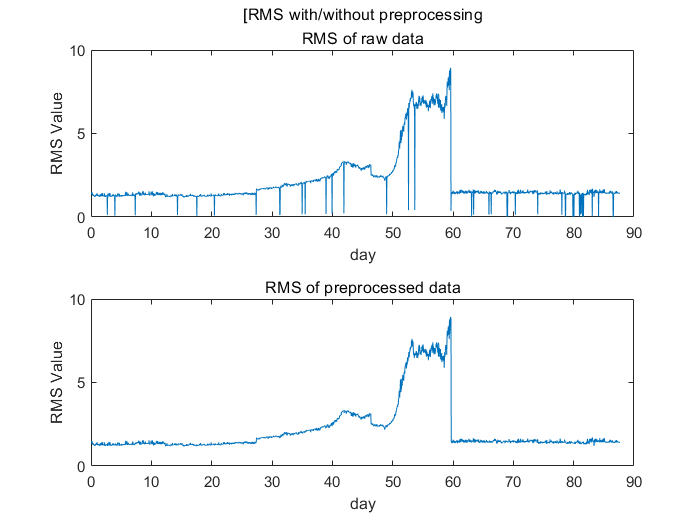

figure;

subplot(2, 1, 1);   plot(d_Full, RAW_bearingFull_RMS);
xlim([0 90]);       ylim([0 10]);       xlabel('day');       ylabel('RMS Value');       subtitle("RMS of raw data")
title('[RMS with/without preprocessing');

subplot(2, 1, 2);   plot(d_Full, Preprocessed_bearingFull_RMS);
xlim([0 90]);       ylim([0 10]);       xlabel('day');       ylabel('RMS Value');       subtitle("RMS of preprocessed data")

## **3-1. Features   :   Statistical Feature Extraction and Analysis**

This code is to check whether there is a sharp difference in the statistical feature value before and after the bearing replacement.

Through this, for the Time Domain Statistical Feature, a significant change in value was observed after the bearing was replaced in the RMS, SRA, and Peak to Peak Value.

For frequency domain statistical features, a significant change in value was shown in all features after bearing replacement.

Therefore, it may be assumed that RMS, SRA, Peak to Peak Value, and Frequency Statistical Features may be key features in the failure diagnosis of bearings.

size_of_data         = size(Preprocessed_bearingFulldata);
number_of_columns    = size_of_data(2);

feature              = table;
for i = 1:number_of_columns
    feature(i,:) = Time_Freq_Features_Calculator(Preprocessed_bearingFulldata(:,i));
end

feature_array = table2array(feature)

feature_array =     1.3983    0.9435    2.9630   -0.0708    9.8100    3.7331    4.6799    5.5325    1.2536    0.7750    0.0170    0.0309    0.0183
    1.4189    0.9617    3.0310   -0.0066   11.0400    4.2568    5.3314    6.2807    1.2524    0.7478    0.0165    0.0313    0.0188
    1.4474    0.9872    2.9381   -0.0462   11.1500    4.1729    5.2053    6.1183    1.2474    0.6694    0.0166    0.0320    0.0193
    1.4989    1.0274    2.8844   -0.0706   10.7100    3.6026    4.4800    5.2562    1.2435    0.5714    0.0160    0.0331    0.0205
    1.3015    0.8825    2.9751   -0.0683    9.8800    3.8493    4.8164    5.6772    1.2513    1.0367    0.0168    0.0288    0.0165
    1.2790    0.8575    2.9437   -0.0305    8.7500    3.4401    4.3252    5.1314    1.2573    1.0999    0.0169    0.0283    0.0160
    1.3810    0.9351    2.9113   -0.0635    9.2800    3.4324    4.2947    5.0692    1.2512    0.8005    0.0161    0.0305    0.0183
    1.2835    0.8723    2.9682   -0.0390    9.7800    3.9814    4.9

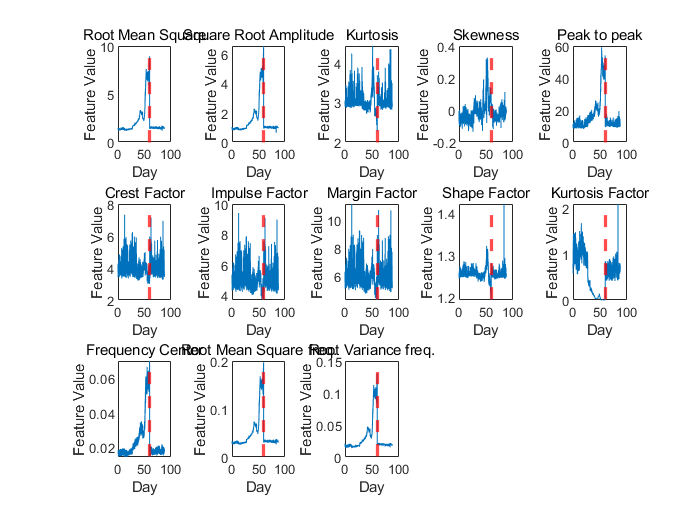

figure;

number_of_columns = width(feature);
for i = 1 : number_of_columns
    subplot(3, 5, i);    plot(d_Full, feature_array(:,i));        xline(59.667, 'r--', "LineWidth", 2);  
    xlabel('Day');       ylabel('Feature Value');
end
      
subplot(3, 5, 1);    subtitle("Root Mean Square");
subplot(3, 5, 2);    subtitle("Square Root Amplitude");         subplot(3, 5, 3);   subtitle("Kurtosis");
subplot(3, 5, 4);    subtitle("Skewness");                      subplot(3, 5, 5);   subtitle("Peak to peak");
subplot(3, 5, 6);    subtitle("Crest Factor");                  subplot(3, 5, 7);   subtitle("Impulse Factor");
subplot(3, 5, 8);    subtitle("Margin Factor");                 subplot(3, 5, 9);   subtitle("Shape Factor");
subplot(3, 5, 10);   subtitle("Kurtosis Factor");               subplot(3, 5, 11);   subtitle("Frequency Center");
subplot(3, 5, 12);   subtitle("Root Mean Square freq.");        subplot(3, 5, 13);   subtitle("Root Variance freq.");

## 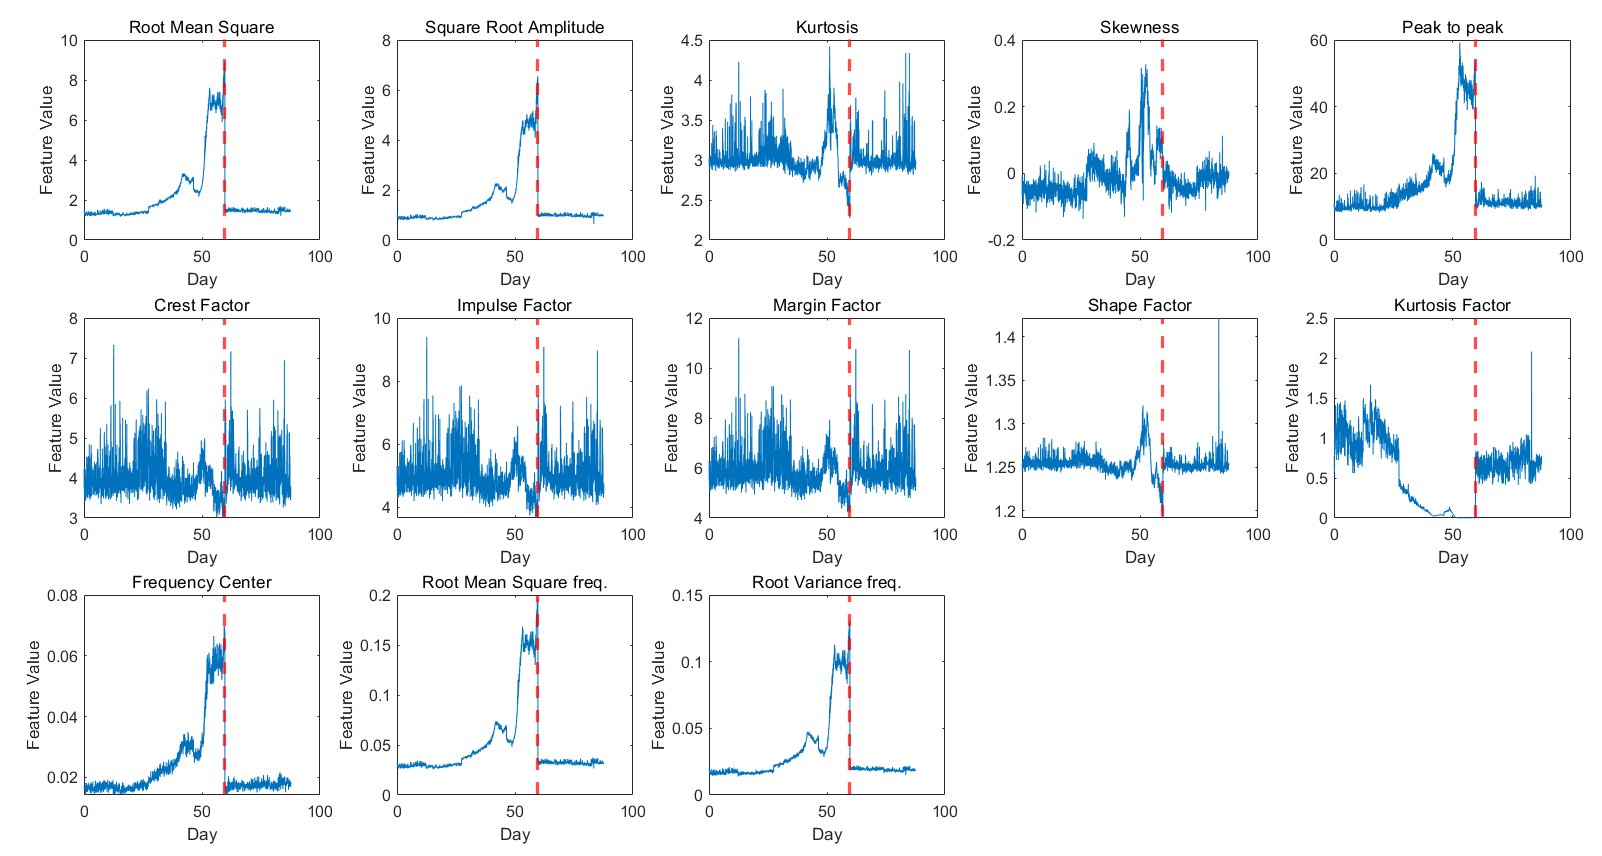

## **3-2. Features   :   FFT of Day**

### **Before Bearing Repair**

This code looks at the failure frequency band [150-190]Hz of the bearing, over time.

As you can see from the graph, the Peak value increases over time in the failure frequency band.

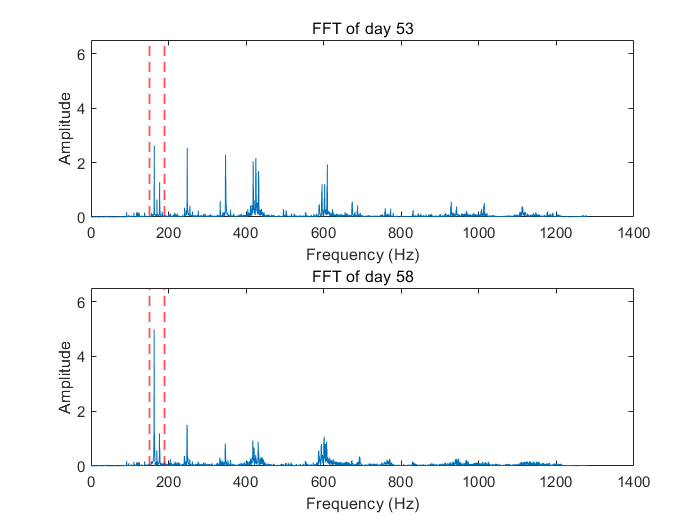

day_53          =  24*53;                             day_53_data        =  Preprocessed_bearingFulldata(:,day_53);
Length_day_53   =  length(day_53_data);               Freq_day_53        =  0 : fs/Length_day_53: fs/2;

figure;                             subplot(2, 1, 1); 
day_53_freq = getFFT(day_53_data,Length_day_53);
plot(Freq_day_53, day_53_freq);     ylim([0,6.5]);           xline(150, 'r--', "LineWidth", 1);          xline(190, 'r--', "LineWidth", 1); 
xlabel('Frequency (Hz)');           ylabel('Amplitude');     title('FFT of day 53');



day_58          =  24*58;                             day_58_data        =  Preprocessed_bearingFulldata(:,day_58);
Length_day_58   =  length(day_58_data);               Freq_day_58        =  0 : fs/Length_day_58: fs/2;
 
subplot(2, 1, 2); 
day_58_freq = getFFT(day_58_data,Length_day_58);
plot(Freq_day_58, day_58_freq);     ylim([0,6.5]);           xline(150, 'r--', "LineWidth", 1);          xline(190, 'r--', "LineWidth", 1); 
xlabel('Frequency (Hz)');           ylabel('Amplitude');     title('FFT of day 58');

### **Before & After Bearing Repair**

Likewise, this code is a code that examines the change in the failure frequency of the bearing over time.

One interesting thing is that after the bearing repair, the Peak value disappeared in the failure frequency band.

Through this, it may be determined that the failure of the bearing occurred before '59', and the repair was performed from 59 to 60 days.

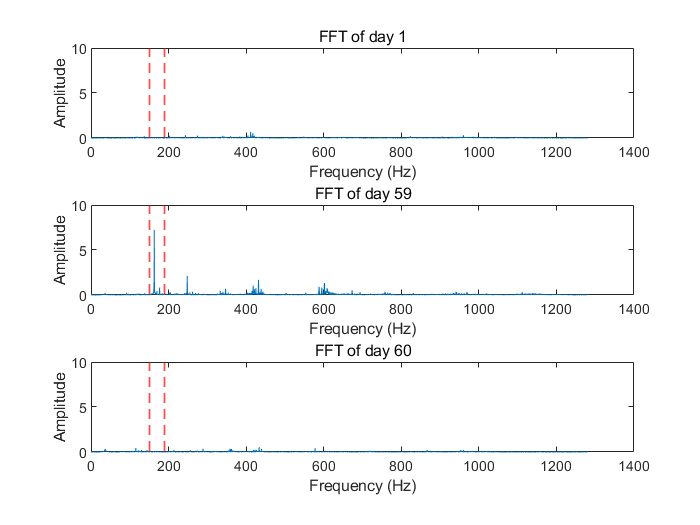

day_60         =  24*1;                                   day_1_data          =  Preprocessed_bearingFulldata(:,day_60);
Length_day_1   =  length(day_1_data);                     Freq_day_1          =  0 : fs/Length_day_1: fs/2;
day_1_freq     =  getFFT(day_1_data,Length_day_1);

figure;
subplot(3, 1, 1); 
plot(Freq_day_1, day_1_freq);
xline(150, 'r--', "LineWidth", 1);                     xline(190, 'r--', "LineWidth", 1); 
ylim([0,10]);   xlabel('Frequency (Hz)');   ylabel('Amplitude');   title('FFT of day 1');



day_59          =  24*59;                                 day_59_data          =  Preprocessed_bearingFulldata(:,day_59);
Length_day_59   =  length(day_59_data);                   Freq_day_59          =  0 : fs/Length_day_59: fs/2;
day_59_freq     =  getFFT(day_59_data,Length_day_59);

subplot(3, 1, 2); 
plot(Freq_day_59, day_59_freq);
xline(150, 'r--', "LineWidth", 1);                      xline(190, 'r--', "LineWidth", 1); 
ylim([0,10]);   xlabel('Frequency (Hz)');   ylabel('Amplitude');   title('FFT of day 59');



day_60          =  24*60;                                 day_60_data          =  Preprocessed_bearingFulldata(:,day_60);
Length_day_60   =  length(day_60_data);                   Freq_day_60          =  0 : fs/Length_day_60: fs/2;
day_60_freq     =  getFFT(day_60_data,Length_day_60);

subplot(3, 1, 3);
plot(Freq_day_60, day_60_freq);
xline(150, 'r--', "LineWidth", 1);                      xline(190, 'r--', "LineWidth", 1); 
ylim([0,10]);   xlabel('Frequency (Hz)');   ylabel('Amplitude');   title('FFT of day 60');

## **3-3. Features   :   FFT Over Time**

With this code, 3D Plotting makes it easy to understand the changes in frequency over time.

It can be confirmed that the failure frequency band increases over time and shows the Max Peak value immediately before repair.

And, immediately after the repair, you can see that the overall frequency is stable.

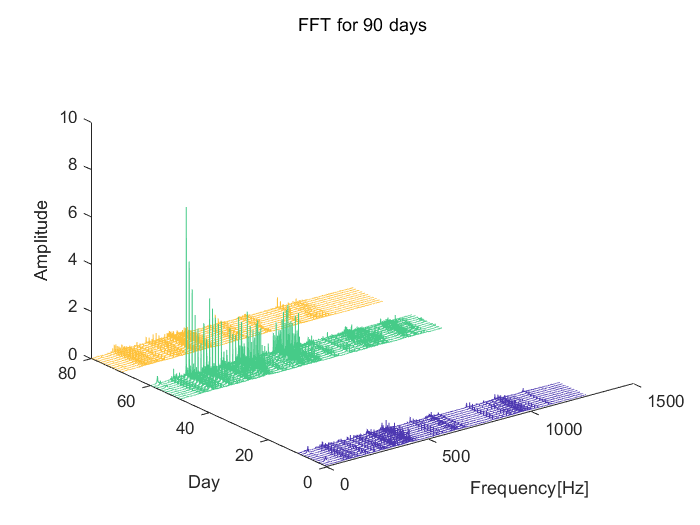

figure;

for i = 24 : 24 : (24*10)+1
    day               =  zeros(4097,1)+i;    
    data              =  Preprocessed_bearingFulldata(:,day(1,1));
    Length_data       =  length(data);
    Freq_day_data     =  0 : fs/Length_data : fs/2;
    day_FFT           =  getFFT(data, Length_data);
    
    plot3( Freq_day_data , day(:,1)/24 , day_FFT , 'color', [77/255, 56/255, 177/255]);
    ylim([0,80]);     zlim([0,10])
    hold on;
end


for i = 24*50 : 24 : (24*60)+1
    day               =  zeros(4097,1)+i;    
    data              =  Preprocessed_bearingFulldata(:,day(1,1));
    Length_data       =  length(data);
    Freq_day_data     =  0 : fs/Length_data : fs/2;
    day_FFT           =  getFFT(data, Length_data);
    
    plot3( Freq_day_data , day(:,1)/24 , day_FFT , 'color', [70/255, 203/255, 136/255]);
    ylim([0,80]);     zlim([0,10])
end


for i = 24*70 : 24 : (24*80)+1
    day               =  zeros(4097,1)+i;    
    data              =  Preprocessed_bearingFulldata(:,day(1,1));
    Length_data       =  length(data);
    Freq_day_data     =  0 : fs/Length_data : fs/2;
    day_FFT           =  getFFT(data, Length_data);
    
    plot3( Freq_day_data , day(:,1)/24 , day_FFT , 'color', [254/255, 193/255, 58/255]);
    ylim([0,80]);     zlim([0,10])
end

xlabel('Frequency[Hz]');     ylabel('Day');     zlabel('Amplitude');     title('FFT for 90 days');
hold off;

## 3-4. Features   :   Bearing Velocity Envelope FFT

Envelope was performed for additional feature extraction to diagnose bearing failures and predict life through them.

However, it was judged that it was somewhat unreasonable to distinguish between normal and abnormal states in the failure frequency band from envelope signal.

This is because, as shown in the graph, no distinctive characteristics were seen.

Therefore, the envelope feature was not considered in the failure diagnosis and life prediction of this bearing.

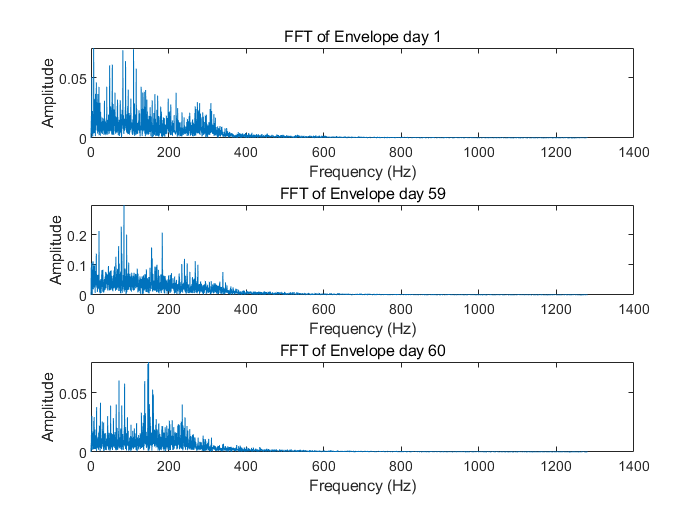

day_1        =  24*1;
day_1_data   =  Preprocessed_bearingFulldata(:,day_1);
[p_EnvNormal, f_EnvNormal, x_EnvNormal, t_EnvNormal] = envspectrum(day_1_data, fs);

figure;
subplot(3, 1, 1); 
plot(f_EnvNormal, p_EnvNormal);
xlabel('Frequency (Hz)');   ylabel('Amplitude');   title('FFT of Envelope day 1');



day_59        =  24*59;
day_59_data   =  Preprocessed_bearingFulldata(:,day_59);
[p_EnvNormal, f_EnvNormal, x_EnvNormal, t_EnvNormal] = envspectrum(day_59_data, fs);

subplot(3, 1, 2); 
plot(f_EnvNormal, p_EnvNormal)
xlabel('Frequency (Hz)');   ylabel('Amplitude');   title('FFT of Envelope day 59');



day_60        =  24*60;
day_60_data   =  Preprocessed_bearingFulldata(:,day_60);
[p_EnvNormal, f_EnvNormal, x_EnvNormal, t_EnvNormal] = envspectrum(day_60_data, fs);

subplot(3, 1, 3); 
plot(f_EnvNormal, p_EnvNormal)
xlabel('Frequency (Hz)');   ylabel('Amplitude');   title('FFT of Envelope day 60');

## **3-5. Features   :   Narrowband Over Time**

This code examines the statistical feature only with values corresponding to the failure frequency band.

In addition, the 'Narrow Band Energy' feature was also added to examine the energy of the failure frequency band.

However, since it is an algorithm that examines the Statistical Feature for data to which 'FFT' is applied to examine frequencies,

only Frequency Statistical Features were included in the Global Feature Table. 

day_FFT            = zeros(4097, 2104); 

Freq_day_data      = 0 : fs/Length_data : fs/2;
drop_column        = find( Freq_day_data(1,:) >= 150  &  Freq_day_data(1,:) <=190 );

drop_column_size   = size(drop_column);
drop_column_size   = drop_column_size(2); 
day_FFT_NarrowBand = zeros(drop_column_size, 2104);

feature_NB              = table;

for i = 1:1:size_data
    day            = zeros(4097,1)+i;    
    data           = Preprocessed_bearingFulldata(:,day(1,1));
    Length_data    = length(data);
    
    day_FFT(:,i)   = getFFT(data,Length_data);
    day_FFT_NarrowBand(:,i)  = day_FFT(drop_column,i);
    
    feature_NB(i,:) = NarrowBand_Feature_Calculator(day_FFT_NarrowBand(:,i));
end

feature_NB_array = table2array(feature_NB)

feature_NB_array = 	1.0e+08 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.6974    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.5362    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.0555    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.4431    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.9444    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0187    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.9116    0.0000    0.0000   

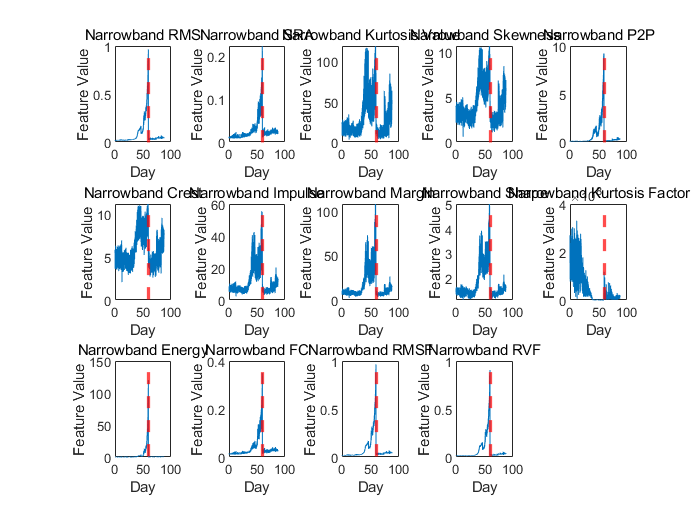

figure;
number_of_columns = width(feature_NB);

for i = 1 : number_of_columns
    subplot(3, 5, i);    plot(d_Full, feature_NB_array(:,i));        xline(59.667, 'r--', "LineWidth", 2);  
    xlabel('Day');       ylabel('Feature Value');                   
end

subplot(3, 5, 1);     subtitle("Narrowband RMS");
subplot(3, 5, 2);     subtitle("Narrowband SRA");
subplot(3, 5, 3);     subtitle("Narrowband Kurtosis Value");
subplot(3, 5, 4);     subtitle("Narrowband Skewness");
subplot(3, 5, 5);     subtitle("Narrowband P2P");
subplot(3, 5, 6);     subtitle("Narrowband Crest");
subplot(3, 5, 7);     subtitle("Narrowband Impulse");
subplot(3, 5, 8);     subtitle("Narrowband Margin");
subplot(3, 5, 9);     subtitle("Narrowband Shape");
subplot(3, 5, 10);    subtitle("Narrowband Kurtosis Factor");
subplot(3, 5, 11);    subtitle("Narrowband Energy");
subplot(3, 5, 12);    subtitle("Narrowband FC");
subplot(3, 5, 13);    subtitle("Narrowband RMSF");
subplot(3, 5, 14);    subtitle("Narrowband RVF");

## **3-6. Features   :   Spectral Kurtosis Over Time**

This code is a code that stores the Spectral Kurtosis Value over time and then gets mean, std, skewness, and kurtosis for this value.

Based on these values, a Global Feature Table will be created and used for failure diagnosis and life prediction of bearings in the future.

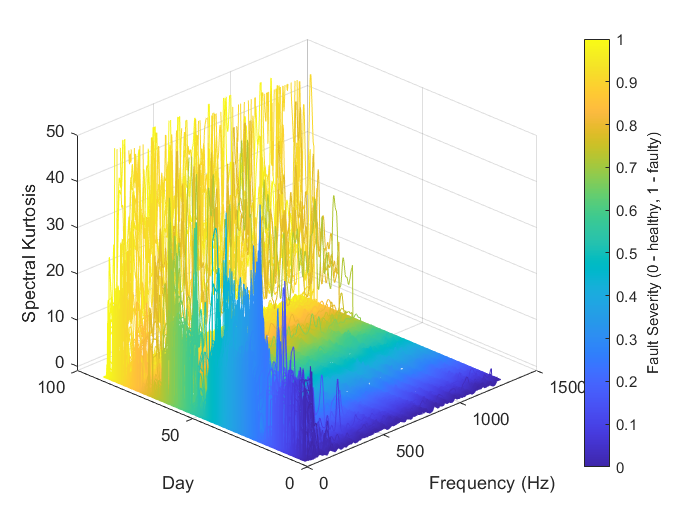

colors  = parula(2104);
day     = 1;
Iteration_Interval = 1;

figure
hold on

feature_SK = table;

for i = 1 : Iteration_Interval : size_data
    % Get vibration signal and measurement date
    v = bearingFulldata(:,i);
    
    % Compute spectral kurtosis with window size = 128
    wc = 128;
    [SK, F] = pkurtosis(v, fs, wc);

    feature_SK(i,:) = SpectralKurtosis_Feature_Calculator(SK);
    
    % Plot the spectral kurtosis
    plot3(F, day*ones(size(F)), SK, 'Color', colors(i, :));
    day = day + Iteration_Interval/24;
end

view(-45, 30);
cbar = colorbar;

xlabel('Frequency (Hz)');
ylabel('Day');
ylabel(cbar, 'Fault Severity (0 - healthy, 1 - faulty)');
zlabel('Spectral Kurtosis');
zlim([-1,50]);

grid on
hold off

feature_SK_array = table2array(feature_SK)

feature_SK_array =    -0.1596    0.2421   -0.1397    2.9061
    0.3631    2.1874    4.3483   21.2560
   -0.1400    0.2986    0.2702    3.1607
   -0.1131    0.2789    0.2290    2.9051
   -0.1480    0.2855   -0.0197    3.0513
   -0.1433    0.2558   -0.1714    3.4375
   -0.1597    0.2532   -0.0014    2.8367
   -0.1151    0.3765    2.9496   19.5921
   -0.1273    0.2803    0.1998    2.9922
   -0.1397    0.2742   -0.0130    3.3213


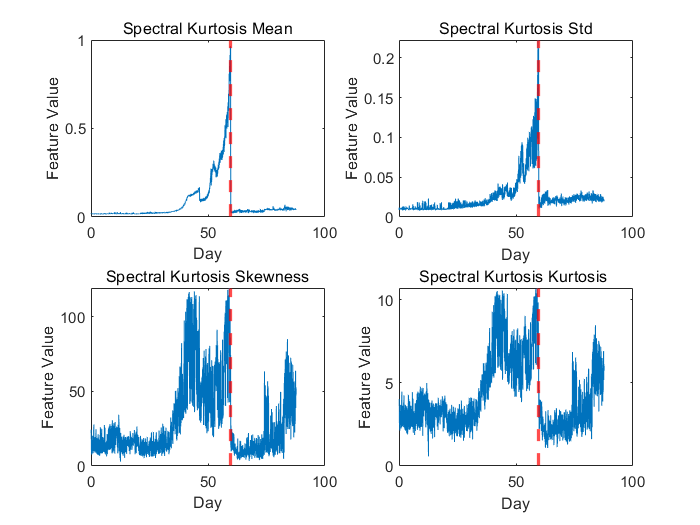

figure;
number_of_columns = width(feature_SK);

for i = 1 : number_of_columns
    subplot(2, 2, i);    plot(d_Full, feature_NB_array(:,i));        xline(59.667, 'r--', "LineWidth", 2);  
    xlabel('Day');       ylabel('Feature Value');                   
end

subplot(2, 2, 1);     subtitle("Spectral Kurtosis Mean");
subplot(2, 2, 2);     subtitle("Spectral Kurtosis Std");
subplot(2, 2, 3);     subtitle("Spectral Kurtosis Skewness");
subplot(2, 2, 4);     subtitle("Spectral Kurtosis Kurtosis ");

## **4-1. Global Features Table**

In the bearing failure diagnosis,

it was judged that accurate analysis could be rather difficult because the data interval was too tight to view all data at time intervals, so the table was defined separately at date intervals.

### **Hour Interval & Full data **Table

Date = datetime(2021,04,14) : hours(1) : datetime(2021,07,14);
Date = transpose(Date);

Date_Confirmed = array2table(Date(1:size_data),"VariableNames","Date")

Date_Confirmed = 2104×1 table
           Date        
    ___________________

    2021-04-14 00:00:00
    2021-04-14 01:00:00
    2021-04-14 02:00:00
    2021-04-14 03:00:00
    2021-04-14 04:00:00
    2021-04-14 05:00:00
    2021-04-14 06:00:00
    2021-04-14 07:00:00
    2021-04-14 08:00:00
    2021-04-14 09:00:00
    2021-04-14 10:00:00
    2021-04-14 11:00:00
    2021-04-14 12:00:00
    2021-04-14 13:00:00
    2021-04-14 14:00:00
    2021-04-14 15:00:00


GlobalFeatureTable = [Date_Confirmed, feature, feature_NB(:,12:14), feature_SK]

GlobalFeatureTable = 2104×21 table
           Date             Xrms      Xsra       Xkv         Xsk        Xppv      Xcf       Xif       Xmf       Xsf        Xkf        Xfc        Xrmsf        Xrvf        NBfc       NBrmsf      NBrvf       SKmean       SKstd        SKsk        SKkv 
    ___________________    ______    _______    ______    __________    _____    ______    ______    ______    ______    _______    ________    ________    ________    ________    ________    ________    _________    _______    __________    ______

    2021-04-14 00:00:00    1.3983    0.94351     2.963     -0.070809     9.81    3.7331    4.6799    5.5325    1.2536    0.77504     0.01698    0.030895    0.018253    0.011078    0.017005    0.012903     -0.15958    0.24205      -0.13965    2.9061
    2021-04-14 01:00:00    1.4189    0.96168     3.031    -0.0065534    11.04    4.2568    5.3314    6.2807    1.2524    0.74781    0.016523     0.03135    0.018841     0.01381    0.019956    0.014406      0.36309    

GlobalfeatureTimeTable    = table2timetable(GlobalFeatureTable)

GlobalfeatureTimeTable = 2104×20 timetable
           Date             Xrms      Xsra       Xkv         Xsk        Xppv      Xcf       Xif       Xmf       Xsf        Xkf        Xfc        Xrmsf        Xrvf        NBfc       NBrmsf      NBrvf       SKmean       SKstd        SKsk        SKkv 
    ___________________    ______    _______    ______    __________    _____    ______    ______    ______    ______    _______    ________    ________    ________    ________    ________    ________    _________    _______    __________    ______

    2021-04-14 00:00:00    1.3983    0.94351     2.963     -0.070809     9.81    3.7331    4.6799    5.5325    1.2536    0.77504     0.01698    0.030895    0.018253    0.011078    0.017005    0.012903     -0.15958    0.24205      -0.13965    2.9061
    2021-04-14 01:00:00    1.4189    0.96168     3.031    -0.0065534    11.04    4.2568    5.3314    6.2807    1.2524    0.74781    0.016523     0.03135    0.018841     0.01381    0.019956    0.014406      0.3

### Day Interval & Before Repair Data Table

Date_Confirmed_reform = array2table(Date(1:24:idx_repair),"VariableNames","Date")   % Day Interval & Before Repair Data

Date_Confirmed_reform = 60×1 table
       Date   
    __________

    2021-04-14
    2021-04-15
    2021-04-16
    2021-04-17
    2021-04-18
    2021-04-19
    2021-04-20
    2021-04-21
    2021-04-22
    2021-04-23
    2021-04-24
    2021-04-25
    2021-04-26
    2021-04-27
    2021-04-28
    2021-04-29


GlobalFeatureTable_reform = [Date_Confirmed_reform, feature(1:24:idx_repair,:), feature_NB(1:24:idx_repair,12:14), feature_SK(1:24:idx_repair,:)]

GlobalFeatureTable_reform = 60×21 table
       Date        Xrms      Xsra       Xkv         Xsk        Xppv      Xcf       Xif       Xmf       Xsf        Xkf        Xfc        Xrmsf        Xrvf        NBfc       NBrmsf      NBrvf       SKmean      SKstd       SKsk        SKkv 
    __________    ______    _______    ______    __________    _____    ______    ______    ______    ______    _______    ________    ________    ________    ________    ________    ________    ________    _______    _________    ______

    2021-04-14    1.3983    0.94351     2.963     -0.070809     9.81    3.7331    4.6799    5.5325    1.2536    0.77504     0.01698    0.030895    0.018253    0.011078    0.017005    0.012903    -0.15958    0.24205     -0.13965    2.9061
    2021-04-15    1.2796    0.86388    2.9576    -0.0010628     9.29    3.6887    4.6253    5.4637    1.2539     1.1032    0.018216    0.028271     0.01529    0.012568    0.017038    0.011504    -0.13272    0.28199      0.33558     3.837
    202

GlobalfeatureTimeTable_reform    = table2timetable(GlobalFeatureTable_reform)

GlobalfeatureTimeTable_reform = 60×20 timetable
       Date        Xrms      Xsra       Xkv         Xsk        Xppv      Xcf       Xif       Xmf       Xsf        Xkf        Xfc        Xrmsf        Xrvf        NBfc       NBrmsf      NBrvf       SKmean      SKstd       SKsk        SKkv 
    __________    ______    _______    ______    __________    _____    ______    ______    ______    ______    _______    ________    ________    ________    ________    ________    ________    ________    _______    _________    ______

    2021-04-14    1.3983    0.94351     2.963     -0.070809     9.81    3.7331    4.6799    5.5325    1.2536    0.77504     0.01698    0.030895    0.018253    0.011078    0.017005    0.012903    -0.15958    0.24205     -0.13965    2.9061
    2021-04-15    1.2796    0.86388    2.9576    -0.0010628     9.29    3.6887    4.6253    5.4637    1.2539     1.1032    0.018216    0.028271     0.01529    0.012568    0.017038    0.011504    -0.13272    0.28199      0.33558     3.837

## 5-1. Feature Postprocessing

### Smoothing

Extracted features are usually associated with noise. The noise with opposite trend can sometimes be harmful to the RUL prediction. In addition, one of the feature performance metrics, monotonicity, to be introduced next is not robust to noise. Therefore, a causal moving mean filter with a lag window of 5 steps is applied to the extracted features, where "causal" means no future value is used in the moving mean filtering.

To sum up, a data post-processing was performed to remove noise.

variableNames       = GlobalfeatureTimeTable.Properties.VariableNames;

GlobalfeatureTimeTableSmooth  = varfun(@(x) movmean(x, [5 0]), GlobalfeatureTimeTable);
GlobalfeatureTimeTableSmooth.Properties.VariableNames = variableNames;

variableNames       = GlobalfeatureTimeTable_reform.Properties.VariableNames;

GlobalfeatureTimeTable_reformSmooth  = varfun(@(x) movmean(x, [5 0]), GlobalfeatureTimeTable_reform);
GlobalfeatureTimeTable_reformSmooth.Properties.VariableNames = variableNames;

### Compare Before Smoothing and After Smoothing   [Not Reformed Table, **Hour Interval & Full data **Table]

Changing the data interval from time to date interval, a neat graph without looking messy was plotted.

Two features were randomly selected and compared before and after Smoothing.

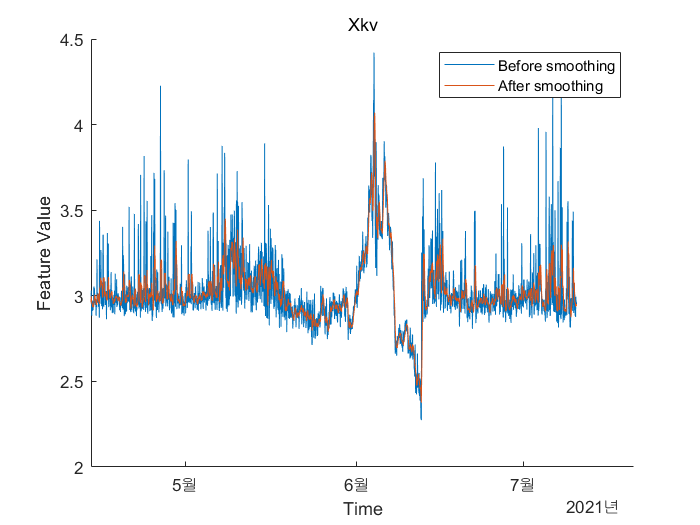

SmoothingPlot(GlobalfeatureTimeTable,GlobalfeatureTimeTableSmooth,GlobalfeatureTimeTable.Xkv,GlobalfeatureTimeTableSmooth.Xkv);  title('Xkv');

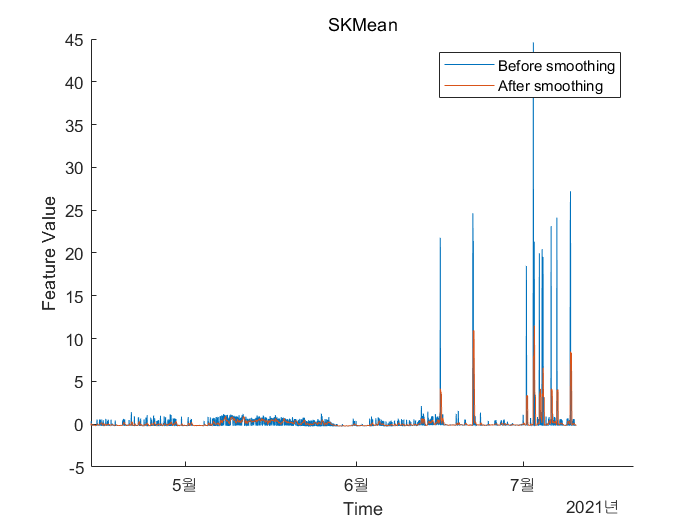

SmoothingPlot(GlobalfeatureTimeTable,GlobalfeatureTimeTableSmooth,GlobalfeatureTimeTable.SKmean,GlobalfeatureTimeTableSmooth.SKmean);  title('SKMean');

### Compare Before Smoothing and After Smoothing   [Reformed Table, Day Interval & Before Repair Data Table]

Two features were randomly selected and compared before and after Smoothing.

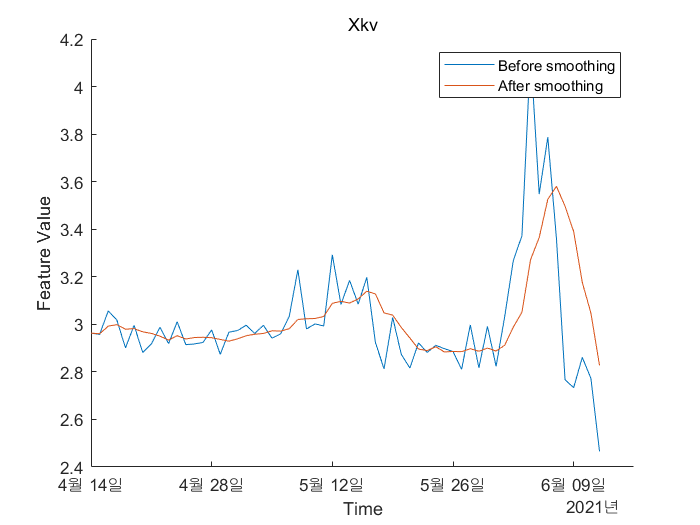

SmoothingPlot(GlobalfeatureTimeTable_reform,GlobalfeatureTimeTable_reformSmooth,GlobalfeatureTimeTable_reform.Xkv,GlobalfeatureTimeTable_reformSmooth.Xkv);  title('Xkv');

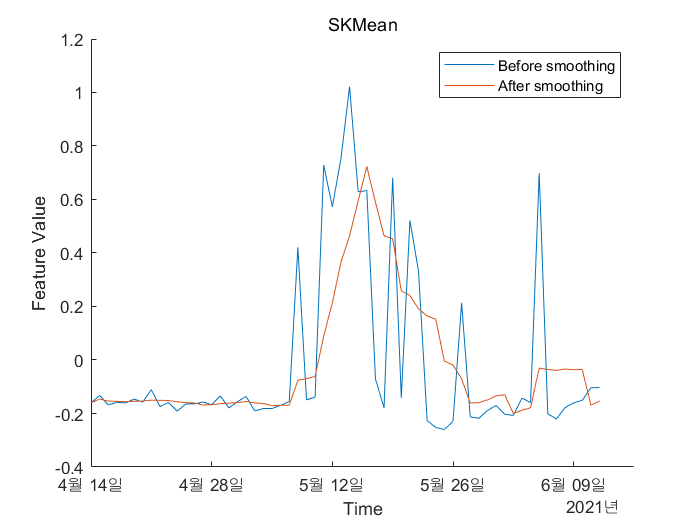

SmoothingPlot(GlobalfeatureTimeTable_reform,GlobalfeatureTimeTable_reformSmooth,GlobalfeatureTimeTable_reform.SKmean,GlobalfeatureTimeTable_reformSmooth.SKmean);  title('SKMean');

## 6-1. Training

### Set Training Data

In practice, the data of the whole life cycle is not available when developing the prognostic algorithm, but it is reasonable to assume that some data in the early stage of the life cycle has been collected. Hence data collected in the first 24 days (40% of the life cycle) is treated as training data. The following feature importance ranking and fusion is only based on the training data.

starttime   = datetime(2021, 04, 24);
startpoint  = find(GlobalfeatureTimeTable_reformSmooth.Date < starttime , 1, 'last');

breaktime   = datetime(2021, 05, 17);
breakpoint  = find(GlobalfeatureTimeTable_reformSmooth.Date < breaktime , 1, 'last');   % 60 * 0.4 = 24 days

trainData   = GlobalfeatureTimeTable_reformSmooth(startpoint:breakpoint, :);

### **Selection of Features**

You need to explain the process cleary and analyze the results

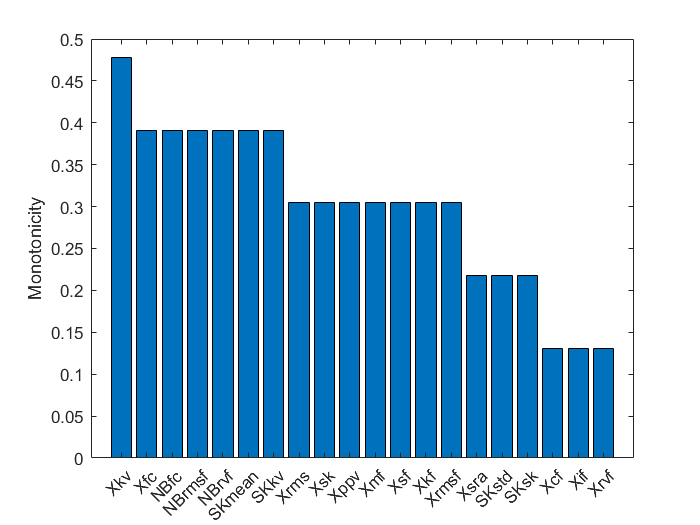

% Since moving window smoothing is already done, set 'WindowSize' to 0 to
% turn off the smoothing within the function
featureImportance = monotonicity(trainData, 'WindowSize', 0);
helperSortedBarPlot(featureImportance, 'Monotonicity');

Kurtosis Value of the signal is the top feature based on the monotonicity. 

Features with feature importance score larger than 0.3 are selected for feature fusion in the next section.

trainDataSelected  = trainData(:, featureImportance{:,:}>0.3);
featureSelected    = GlobalfeatureTimeTable_reformSmooth(:, featureImportance{:,:}>0.3)

featureSelected = 60×14 timetable
       Date        Xrms      Xkv         Xsk        Xppv      Xmf       Xsf        Xkf        Xfc        Xrmsf        NBfc       NBrmsf      NBrvf       SKmean      SKkv 
    __________    ______    ______    _________    ______    ______    ______    _______    ________    ________    ________    ________    ________    ________    ______

    2021-04-14    1.3983     2.963    -0.070809      9.81    5.5325    1.2536    0.77504     0.01698    0.030895    0.011078    0.017005    0.012903    -0.15958    2.9061
    2021-04-15    1.3389    2.9603    -0.035936      9.55    5.4981    1.2538    0.93914    0.017598    0.029583    0.011823    0.017022    0.012203    -0.14615    3.3716
    2021-04-16    1.3226    2.9924    -0.036822       9.9    5.8432    1.2546    0.99399     0.01717    0.029223    0.011952    0.017042    0.012119     -0.1534     3.236
    2021-04-17    1.3265    2.9988    -0.043276      9.98    5.8027    1.2537    0.98087    0.016666    0.0293

## 6-2. Dimension Reduction and Feature Fusion

Principal Component Analysis (PCA) is used for dimension reduction and feature fusion.

Before performing PCA, it is a good practice to normalize the features into the same scale. 

### Normalize Train Data

Note that PCA coefficients and the mean and standard deviation used in normalization are obtained from training data, and applied to the entire dataset.

meanTrain            = mean(trainDataSelected{:,:});
sdTrain              = std(trainDataSelected{:,:});
trainDataNormalized  = (trainDataSelected{:,:} - meanTrain)./sdTrain;
coef                 = pca(trainDataNormalized);

The mean, standard deviation and PCA coefficients are used to process the entire data set.

PCA1  = (featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 1);
PCA2  = (featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 2);

Visualize the data in the space of the first two principal components.

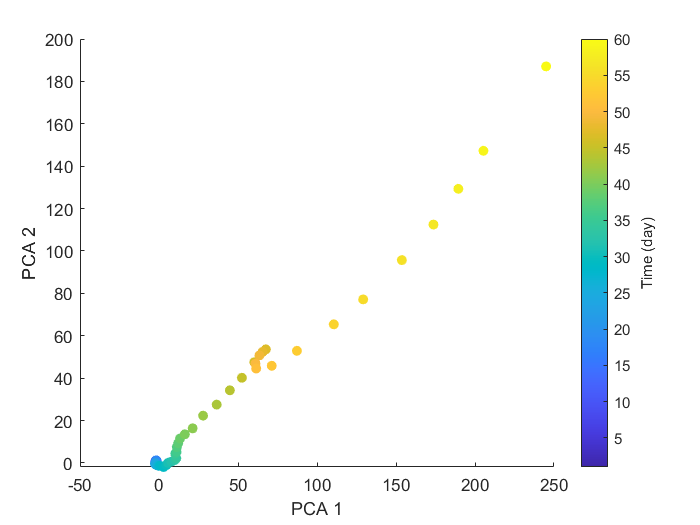

figure
timeUnit = 'day';
 
numData = size(GlobalfeatureTimeTable_reform, 1);
scatter(PCA1, PCA2, [], 1:numData, 'filled')
xlabel('PCA 1');   ylabel('PCA 2')
cbar = colorbar;
ylabel(cbar, ['Time (' timeUnit ')'])

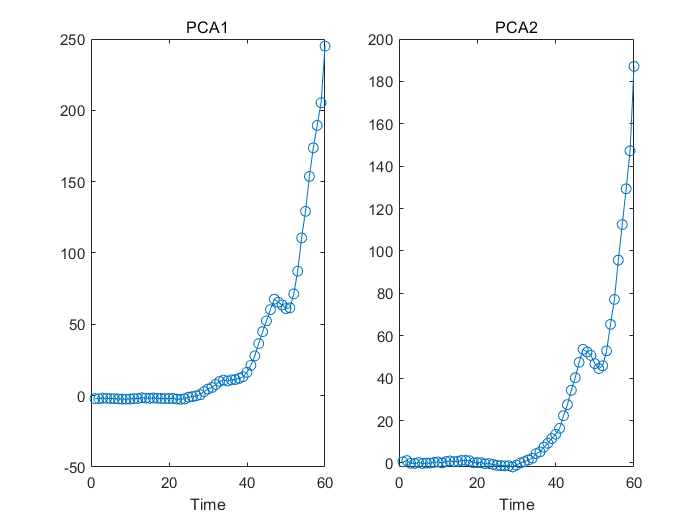

figure
subplot(1,2,1); plot(PCA1, '-o'); xlabel('Time'); subtitle('PCA1');
subplot(1,2,2); plot(PCA2, '-o'); xlabel('Time'); subtitle('PCA2');

The plot indicates that the first principal component is increasing as the machine approaches to failure. Therefore, the first principal component is a promising fused health indicator.

healthIndicator = PCA1;

Visualize the health indicator.

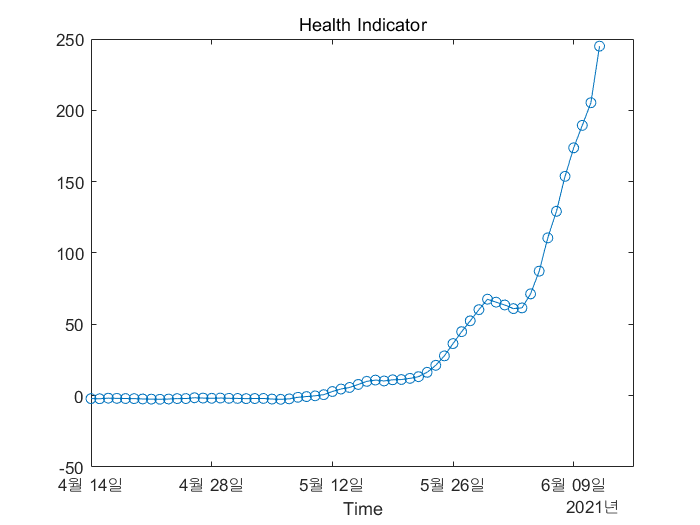

figure
plot(featureSelected.Date, healthIndicator, '-o');   xlabel('Time');   title('Health Indicator')

## 7-1. Fault Monitoring, Warning and RUL Estimation 

Here an Exponential Degradation Model is fit to the health indicator extracted in the last section, and the performances is evaluated in the next section.

First shift the health indicator so that it starts from 0.

healthIndicator = healthIndicator - healthIndicator(1);

The selection of threshold is usually based on the historical records of the machine or some domain-specific knowledge. Since no historical data is available in this dataset, the last value of the health indicator is chosen as the threshold. It is recommended to choose the threshold based on the smoothed (historical) data so that the delay effect of smoothing will be partially mitigated.

threshold = healthIndicator(end);

Now create an exponential degradation model

mdl = exponentialDegradationModel(...
    'Theta', 1, ...
    'ThetaVariance', 1e6, ...
    'Beta', 1, ...
    'BetaVariance', 1e6, ...
    'Phi', -1, ...
    'NoiseVariance', (0.1*threshold/(threshold + 1))^2, ...
    'SlopeDetectionLevel', 0.05);

Use `predictRUL` and `update` methods to predict the RUL and update the parameter distribution in real time.

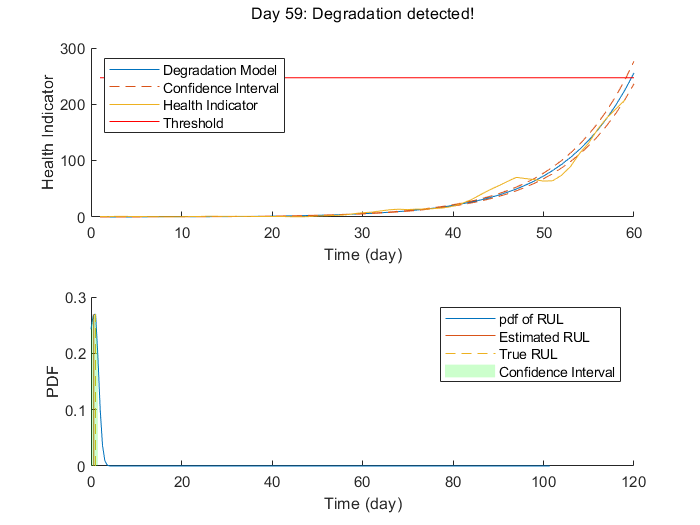

% Keep records at each iteration
totalDay = length(healthIndicator) - 1;
estRULs  = zeros(totalDay, 1);
trueRULs = zeros(totalDay, 1);
CIRULs   = zeros(totalDay, 2);
pdfRULs  = cell(totalDay, 1);

% Create figures and axes for plot updating
figure
ax1 = subplot(2, 1, 1);
ax2 = subplot(2, 1, 2);

for currentDay = 1:totalDay
    
    % Update model parameter posterior distribution
    update(mdl, [currentDay healthIndicator(currentDay)])
    
    % Predict Remaining Useful Life
    [estRUL, CIRUL, pdfRUL] = predictRUL(mdl, ...
                                         [currentDay healthIndicator(currentDay)], ...
                                         threshold);
    trueRUL = totalDay - currentDay + 1;
    
    % Updating RUL distribution plot
    helperPlotTrend(ax1, currentDay, healthIndicator, mdl, threshold, timeUnit);
    helperPlotRUL(ax2, trueRUL, estRUL, CIRUL, pdfRUL, timeUnit)
    
    % Keep prediction results
    estRULs(currentDay) = estRUL;
    trueRULs(currentDay) = trueRUL;
    CIRULs(currentDay, :) = CIRUL;
    pdfRULs{currentDay} = pdfRUL;
    
    % Pause 0.1 seconds to make the animation visible
    pause(0.1)
end

**As the breakdown is imminent, it seems that the specified threshold value has been reached, so it has been properly learned and prediction has been successful.**

## 7-2. Performance Analysis

$\alpha$-$\lambda$ plot is used for prognostic performance analysis [5], where $\alpha \;$bound is set to 20%. The probability that the estimated RUL is between the $\alpha$ bound of the true RUL is calculated as a performance metric of the model:


$$\Pr \left(r^* \left(t\right)-\alpha r^* \left(t\right)<r\left(t\right)<r^* \left(t\right)+\alpha r^* \left(t\right)\left|\Theta \left(t\right)\right.\right)$$


where $r\left(t\right)$ is the estimated RUL at time $t$, $r^* \left(t\right)$ is the true RUL at time $t$, $\Theta \left(t\right)$ is the estimated model parameters at time $t$.

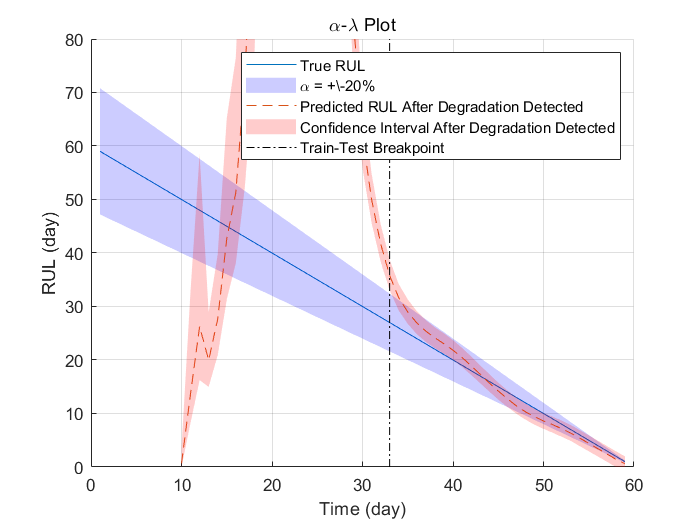

alpha = 0.2;
detectTime = mdl.SlopeDetectionInstant;
prob = helperAlphaLambdaPlot(alpha, trueRULs, estRULs, CIRULs, ...
    pdfRULs, detectTime, breakpoint, timeUnit);
title('\alpha-\lambda Plot')

**'True RUL at time' and 'predicted RUL at time' have corresponded in the confidence interval after break-point.**

**It can be seen that 'RUL prediction' was made accurately based on learning.**

Since the preset prior does not reflect the true prior, the model usually need a few time steps to adjust to a proper parameter distribution. The prediction becomes more accurate as more data points are available.

Visualize the probability of the predicted RUL within the $\alpha \;$bound.

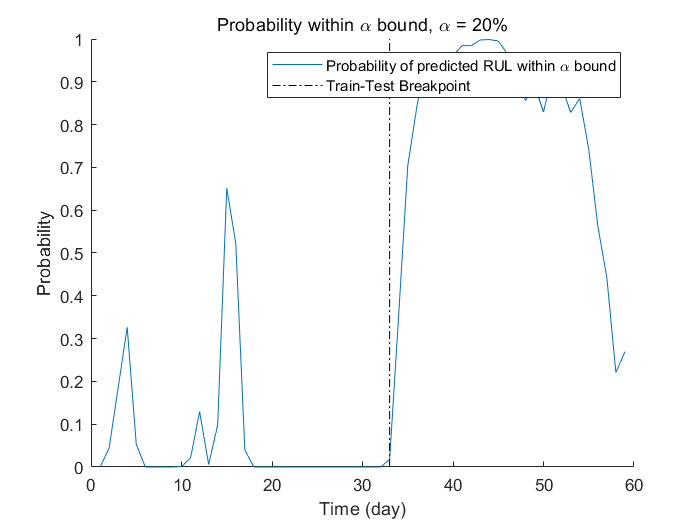

figure
t = 1:totalDay;
hold on
plot(t, prob)
plot([breakpoint breakpoint], [0 1], 'k-.')
hold off
xlabel(['Time (' timeUnit ')'])
ylabel('Probability')
legend('Probability of predicted RUL within \alpha bound', 'Train-Test Breakpoint')
title(['Probability within \alpha bound, \alpha = ' num2str(alpha*100) '%'])

## 8-1. Discussion 

    In this LAB, 'Remaining Useful Life' was predicted based on the bearing dataset of the time series and compared with the actual RUL value.

    The difference between before and after the failure could be derived from Dataset over 90 days to 'Before Repair Dataset' for about 60 days , 'After Repair Dataset' for about 30 days. Through the dataset with these characteristic, it was eventually possible to get features for the fault. That is, the 'Global Feature Table' was created after obtaining the 'Time Statistical Features', 'Frequency Statistical Features', 'Narrow-Band Frequency Statistical Features', and 'Spectral Kurtosis Features', respectively.

    Especially among many features, life prediction through more efficient and accurate learning becomes possible if only specific features can be identified that best reflect the failure characteristics of the actual bearing. Therefore, I went through the process of selecting good features through Monotonicity.

    After that, a health indicator was obtained through the PCA, and the health indicator was fitted to the exponential function. Therefore, it was important to select an appropriate train dataset and set the Monotonicity Threshold value so that the health indicator could be in the form of an exponential function.

    Through this process, it was possible to predict the state of the bearing and the RUL with the finally fitted health indicator.

**One of the difficulties is as follows.**

As mentioned earlier, the proper train dataset selection and the setting of the Monotonicity Threshold value had a significant impact on the RUL prediction performance. Therefore, there have been many trials and errors in determining the above values. Thus, If there is a chance next time, it was thought that it was necessary to think about ways to increase the RUL prediction performance without relying on trial and error.

## 9-1. Reference

[1] Heterogeneous Feature Models and Feature Selection Applied to Bearing Fault Diagnosis, Thomas W. Rauber, Member, IEEE , Francisco de Assis Boldt, and Flávio Miguel Varejão

[2] Prognosis of the Remaining Useful Life of Bearings in a Wind Turbine Gearbox, Wei Teng, Xiaolong Zhang, Yibing Liu, Andrew Kusiak and Zhiyong Ma

[3] 2022-1 DigitalTwin&Automation Lecture and hands-on materials, ykkim, handong global university. 